### **Método das Secantes**


$$x^{k+1} = \frac{x^{k-1}f(x^{k})-x^{k}f(x^{k-1})}{f(x^{k})- f(x^{k-1})$$


VVamos encontrar o zero da função $f(x) = -0.5x^{2}+2.5x+4.5$ no intervalo de $[-2.5,0]$utilizando o método das Secantes, com  chute inicial $x^{0} = -2$ e $x^{1} = 0$ erro relativo igual ou menor que $10^{-4}$.

**Graficamente, **

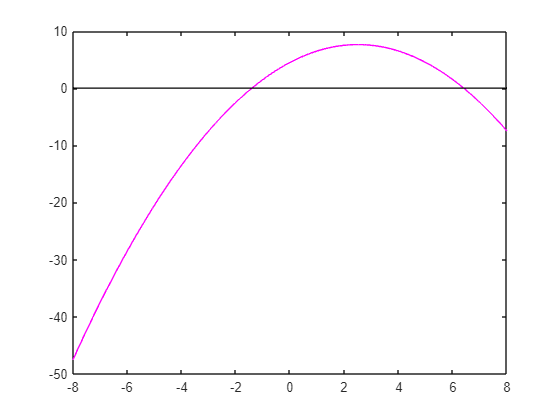

x= -8:0.01:8;
y = fun(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off

**Implementação do Newton-Raphson**

x0 = -1;
x1 = 0;
tol = 10^-4;
k = 0;
erro_relativo = 10;

while erro_relativo > tol
    k = k+1;
    x = (x0.*fun(x1) - x1.*fun(x0))/(fun(x1) - fun(x0));
    xk(k, :) = x0;
    fk(k, :) = fun(x0);
    erro_relativo = abs(x1 - x0)/abs(x1)
    erro_relk(k, :) = erro_relativo;
    x0 = x1;
    x1 = x;
end

erro_relativo = Inf

erro_relativo = 1

erro_relativo = 0.0833

erro_relativo = 0.0144

erro_relativo = 1.7610e-04

erro_relativo = 4.6246e-07


x

x = -1.4051

**Definindo as funções que serão utilizadas:**

function f1 = fun(x)
    f1 = -0.5*x.^2 +2.5*x + 4.5;
end
